% Load the unlabeled image
img = imread("ocean.jpg");

% Load the model trained using hand-selected features
load("gcClassifierSaturation.mat","gcClassifierSaturation");
% Load the model trained using automatically generated features
load("gcClassifierBag.mat","gcClassifierBag");

% Load bag of visual words object created by bagOfFeatures
load("bag.mat","bag");

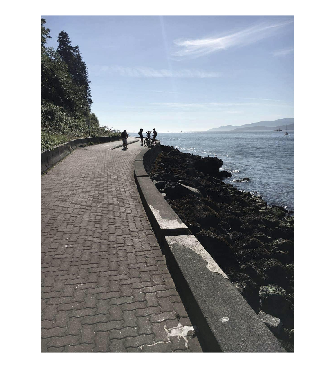

imshow(img);

% Once you are done completing the steps below, paste your code into the
% online MATLAB grading tool to check your work.

% Step 1: Create a table of saturation-based predictor features
img = im2double(img);
imgHSV = rgb2hsv(img);
imgSaturation = imgHSV(:,:,2);
avgSat = mean(imgSaturation(:));
stdSat = std(imgSaturation(:));
gcTableSaturation = table(avgSat,stdSat);

% Step 2: Create a table of bagOfFeatures-based predictor features
predFeats = encode(bag, img);

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


featNames = "f" + string(1:500);
gcTableBag = array2table(predFeats,"VariableNames",featNames);

% Step 3: Use gcClassifierSaturation.predictFcn to classify the unlabeled
% image
gcTableSaturation.prediction = gcClassifierSaturation.predictFcn(gcTableSaturation);
gcTableSaturation

gcTableSaturation = 1×3 table
    avgSat    stdSat     prediction
    ______    _______    __________

    0.1436    0.07314       Snow   


% Step 4: Use gcClassifierBag.predictFcn to classify the unlabeled image
gcTableBag.prediction = gcClassifierBag.predictFcn(gcTableBag);
gcTableBag

gcTableBag = 1×501 table
      f1          f2           f3          f4          f5          f6          f7          f8          f9           f10          f11         f12          f13       f14    f15     f16       f17         f18         f19        f20          f21         f22          f23          f24         f25         f26         f27         f28         f29       f30    f31      f32         f33         f34         

*Copyright 2022 The MathWorks, Inc.*